# 1.1

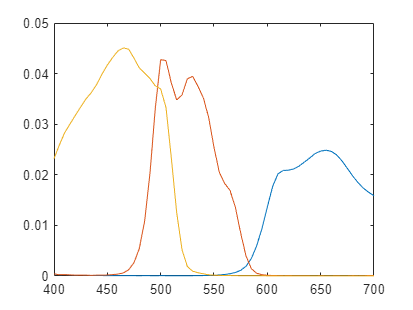

n = length(Ad);
x = linspace(400,700,n);
plot(x,Ad)

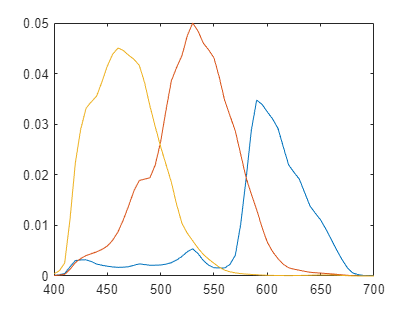

plot(x,Ad2)

Ad & Ad2 looks similar but not exact. They will definitly give different outputs. We think Ad2 will give a higher contrast image.

Answer: No.

# 1.2

## Camera 1

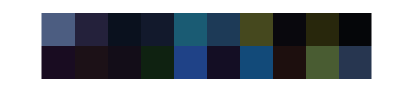

e = CIED65 .* chips20;

% raw (i.e. un-calibrated) camera output for the 20 surfaces
d = Ad'*e';

showRGB(d')

## Camera 2

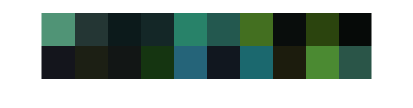

% raw (i.e. un-calibrated) camera output for the 20 surfaces
d = Ad2'*e';

showRGB(d')

# 2.1

% Taking a photo of a  completely white image
ref1 = Ad'*ones(1,61)';
ref2 = Ad2'*ones(1,61)';

% Computing the normalization values
cf1 = ones(3,1) ./ ref1

cf1 =     2.1574
    1.7711
    1.1649


cf2 = ones(3,1) ./ ref2

cf2 =     2.1161
    1.1433
    1.3476


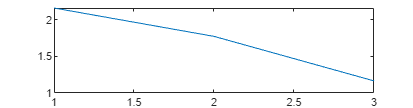


plot(cf1)

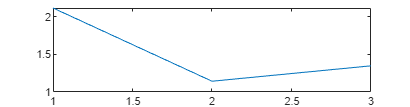

plot(cf2)

# 2.2

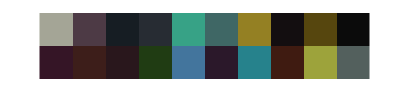

% Calculating RAW RGB values for both cameras under the same light source
e = CIED65 .* chips20;

RAW_C1_CIED65 = Ad'*e';
RAW_C2_CIED65 = Ad2'*e';

% Calibrating the values
CAL_DATA_C1_CIED65 = RAW_C1_CIED65 .* cf1;
CAL_DATA_C2_CIED65 = RAW_C2_CIED65 .* cf2;
 
showRGB(CAL_DATA_C1_CIED65')

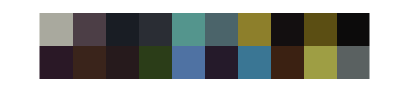

showRGB(CAL_DATA_C2_CIED65')

# 2.3

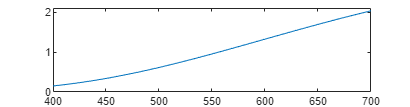

n = length(CIEA);
x = linspace(400,700,n);
plot(x,CIEA)
ylim([0,2.1])

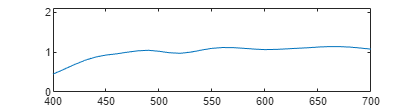

plot(x,CIEB)
ylim([0,2.1])

# 2.4

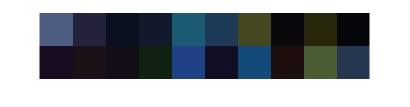

e = CIED65 .* chips20;
e2 = CIEA .* chips20;

% 1 Taking a picture of 20 surfaces
d1_raw_65 = Ad'*e';
d1_raw_CIEA = Ad'*e2';

% 2 Taking a picture of a completely white surface (ones)
d1_raw_65_v = Ad'*CIED65';
d1_raw_CIEA_v = Ad'*CIEA';

% 3 Calibration factors, same!
cf1 = ones(3,1) ./ d1_raw_65_v;
cf2 = ones(3,1) ./ d1_raw_CIEA_v;

% 1 multiplied with calibration factors
RGB_cal_CIE65 = d1_raw_65 .* cf1;
RGB_cal_CIEA = d1_raw_CIEA .* cf2;

showRGB(d1_raw_65')

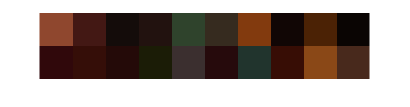

showRGB(d1_raw_CIEA')

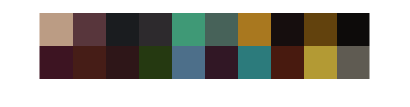


showRGB(RGB_cal_CIE65')

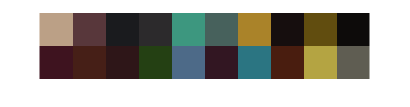

showRGB(RGB_cal_CIEA')

# 2.5

% d = Ad' * (chips20 .* CIEA)'
e = CIED65 .* chips20;
e2 = CIEA .* chips20;

% 1 Taking a picture of 20 surfaces
d1_raw_65 = Ad'*e';
d1_raw_CIEA = Ad'*e2';

% Calculating the reference image (taking a picture of white surface)
ref1 = Ad'*CIED65';
ref2 = Ad'*CIEA';

% Normalizing and calculating the calibration factors 
cf = ones(3,1) ./ ref1;
cf2 = ones(3,1) ./ ref2;

% Scaling
RGB_cal_D65 = d1_raw_65 .* cf;
RGB_cal_A = d1_raw_CIEA .* cf2;

showRGB(RGB_cal_D65')

showRGB(RGB_cal_A')

# 3.1

% Calculating the exact xyz values from RBG, our "correct" values
k = 100 ./ (CIED65 * xyz(:,2))

k = 4.6460


xyzValuesFromSpectra = xyz'*( CIED65 .* chips20 )' * k

xyzValuesFromSpectra =    66.5076   29.1415   10.3354   17.0944   37.2524   31.4696   51.8681    7.1516   35.7168    4.5704   14.7977   21.2515   13.6952   19.1563   34.5574   13.8335   26.8255   20.8937   59.1042   36.1553
   67.2653   25.9561   10.4588   16.8158   49.3000   35.3276   57.1830    6.4429   38.2742    4.5382   10.4425   18.0936   11.4180   25.1057   36.1143   10.5687   34.9493   17.7770   67.6801   37.2942
   61.0087   28.3929   14.4753   20.9340   50.2915   40.5003   10.0020    6.4265    5.4609    4.4085   16.5167   10.6582   11.4388    7.5209   65.7332   18.0017   54.8397    6.5922   17.7720   37.8082


# 3.2

Approx XYZ values in different ways 3.2, 3.4, 3.5

CAL_DATA_C1_CIED65_XYZ = M_XYZ2RGB \ CAL_DATA_C1_CIED65

CAL_DATA_C1_CIED65_XYZ =    60.2807   25.3819   10.2413   16.1157   41.0190   31.7965   44.3620    6.1891   24.7008    4.1275   14.3237   15.9949   11.7908   14.9757   38.4732   13.3662   34.4431   15.2347   52.5084   33.5394
   64.2045   24.5310   11.1173   17.0764   53.6754   37.1004   49.1332    6.0519   27.1619    4.3659   11.4666   14.3452   10.7111   20.0372   42.9575   11.5931   43.7467   13.3826   60.5896   36.5763
   64.9263   28.8888   14.6345   21.3417   57.7292   43.0964   20.1329    6.6462    9.2427    4.6809   15.6652   11.6850   11.7060   10.3007   64.5800   17.0730   58.7151    7.9590   30.6806   39.8123


C_XYZ = CAL_DATA_C1_CIED65_XYZ

C_XYZ =    60.2807   25.3819   10.2413   16.1157   41.0190   31.7965   44.3620    6.1891   24.7008    4.1275   14.3237   15.9949   11.7908   14.9757   38.4732   13.3662   34.4431   15.2347   52.5084   33.5394
   64.2045   24.5310   11.1173   17.0764   53.6754   37.1004   49.1332    6.0519   27.1619    4.3659   11.4666   14.3452   10.7111   20.0372   42.9575   11.5931   43.7467   13.3826   60.5896   36.5763
   64.9263   28.8888   14.6345   21.3417   57.7292   43.0964   20.1329    6.6462    9.2427    4.6809   15.6652   11.6850   11.7060   10.3007   64.5800   17.0730   58.7151    7.9590   30.6806   39.8123


REF_XYZ = xyzValuesFromSpectra

REF_XYZ =    66.5076   29.1415   10.3354   17.0944   37.2524   31.4696   51.8681    7.1516   35.7168    4.5704   14.7977   21.2515   13.6952   19.1563   34.5574   13.8335   26.8255   20.8937   59.1042   36.1553
   67.2653   25.9561   10.4588   16.8158   49.3000   35.3276   57.1830    6.4429   38.2742    4.5382   10.4425   18.0936   11.4180   25.1057   36.1143   10.5687   34.9493   17.7770   67.6801   37.2942
   61.0087   28.3929   14.4753   20.9340   50.2915   40.5003   10.0020    6.4265    5.4609    4.4085   16.5167   10.6582   11.4388    7.5209   65.7332   18.0017   54.8397    6.5922   17.7720   37.8082



[L, a, b] =  xyz2lab(C_XYZ(1,:)', C_XYZ(2,:)', C_XYZ(3,:)');

C_LAB = zeros(3,20);
C_LAB(1,:) = L;
C_LAB(2,:) = a;
C_LAB(3,:) = b;

[L, a, b] =  xyz2lab(REF_XYZ(1,:)', REF_XYZ(2,:)', REF_XYZ(3,:)');

REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;

dE = euclidean_distance_lab(REF_LAB, C_LAB)

dE =     9.7097    9.6861    5.8894    6.8658    3.6894    4.8642   31.6232    6.2942   30.9023    4.3929   11.5236   13.6695    8.0973   18.7341   13.5244   11.5684    9.7725   16.8241   27.8545    7.3514



mean(dE)

ans = 12.6418

max(dE)

ans = 31.6232

# 3.3

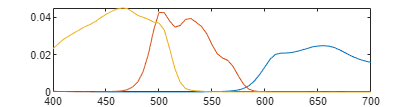

plot(x, Ad)

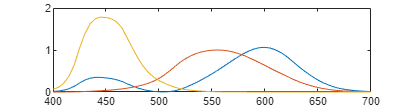

plot(x, xyz)

# 3.4

load CAL_DATA_C1_CIED65.mat
D = CAL_DATA_C1_CIED65'

D =     0.6428    0.6472    0.5890
    0.3014    0.2262    0.2695
    0.0880    0.1154    0.1377
    0.1533    0.1730    0.1998
    0.2163    0.6334    0.5237
    0.2452    0.4057    0.3977
    0.5819    0.5001    0.1373
    0.0744    0.0563    0.0614
    0.3368    0.2740    0.0560
    0.0433    0.0438    0.0429


C = xyzValuesFromSpectra'

C =    66.5076   67.2653   61.0087
   29.1415   25.9561   28.3929
   10.3354   10.4588   14.4753
   17.0944   16.8158   20.9340
   37.2524   49.3000   50.2915
   31.4696   35.3276   40.5003
   51.8681   57.1830   10.0020
    7.1516    6.4429    6.4265
   35.7168   38.2742    5.4609
    4.5704    4.5382    4.4085


A = pinv(D)*C

A =    65.8613   40.3725    4.9525
   31.0366   76.3730  -16.5941
    5.1530  -15.5468  115.2712



xyz_aprox = D * A

xyz_aprox =    65.4559   66.2204   60.3402
   28.2594   25.2527   28.8067
   10.0878   10.2237   14.3996
   16.4985   16.2988   20.9164
   36.6042   48.9640   50.9269
   30.7919   34.7039   40.3202
   54.5556   59.5546   10.4098
    6.9636    6.3498    6.5079
   30.9761   33.6520    3.5824
    4.4338    4.4301    4.4298



[L, a, b] =  xyz2lab(xyz_aprox(:,1), xyz_aprox(:,2), xyz_aprox(:,3));

APROX_LAB = zeros(3,20);
APROX_LAB(1,:) = L;
APROX_LAB(2,:) = a;
APROX_LAB(3,:) = b;

dE = euclidean_distance_lab(APROX_LAB, REF_LAB)

dE =     0.6220    1.9528    0.6893    1.3632    1.5809    0.8824    2.0895    1.1494    5.0249    0.8467    5.8376    3.5886    1.1359    4.7715    1.2010    2.9805    2.5532    3.0985    1.4239    1.1619


mean(dE)

ans = 2.1977

max(dE)

ans = 5.8376

# 3.5

D = CAL_DATA_C1_CIED65'

D =     0.6428    0.6472    0.5890
    0.3014    0.2262    0.2695
    0.0880    0.1154    0.1377
    0.1533    0.1730    0.1998
    0.2163    0.6334    0.5237
    0.2452    0.4057    0.3977
    0.5819    0.5001    0.1373
    0.0744    0.0563    0.0614
    0.3368    0.2740    0.0560
    0.0433    0.0438    0.0429


C = xyzValuesFromSpectra'

C =    66.5076   67.2653   61.0087
   29.1415   25.9561   28.3929
   10.3354   10.4588   14.4753
   17.0944   16.8158   20.9340
   37.2524   49.3000   50.2915
   31.4696   35.3276   40.5003
   51.8681   57.1830   10.0020
    7.1516    6.4429    6.4265
   35.7168   38.2742    5.4609
    4.5704    4.5382    4.4085


A11 = Optimize_poly(D', C')

A11 =    -0.7995   -0.8977   -0.3789
   85.5911   56.8389    6.0983
   60.4722  107.5935    2.4209
  -26.5614  -44.6948  102.5657
  -74.4046  -62.4750  -15.6868
   37.5949   21.9068  -10.6312
    6.4021    7.5442   15.8907
  -56.3742  -46.3906   -1.0092
   39.3495   16.5108  -47.5397
   -5.4670    3.5708   28.7059


xyz_aprox_a11 = Polynomial_regression(D', A11)

xyz_aprox_a11 =    66.5096   27.8573    9.7750   16.6392   36.9511   32.1922   52.3149    7.0672   34.8667    4.3226   15.8613   20.8865   14.1754   19.8283   34.5017   13.8445   26.9130   21.3759   58.9062   36.5895
   67.2542   24.9010    9.9852   16.4765   49.0317   35.9394   57.5626    6.3649   37.3760    4.2559   11.2072   17.8821   11.9189   25.7486   36.1026   10.4850   35.0129   18.3282   67.5508   37.6216
   60.9787   28.5960   14.3552   20.9662   50.1102   40.5785    9.8074    6.3964    5.0991    4.3336   16.2770   10.9571   11.5759    7.7201   65.7413   17.6776   55.0127    6.9452   18.0166   37.6376



[L, a, b] =  xyz2lab(xyz_aprox_a11(1,:)', xyz_aprox_a11(2,:)', xyz_aprox_a11(3,:)');

APROX_LAB = zeros(3,20);
APROX_LAB(1,:) = L;
APROX_LAB(2,:) = a;
APROX_LAB(3,:) = b;

dE = euclidean_distance_lab(APROX_LAB, REF_LAB)

dE =     0.0337    2.3631    1.6165    1.1127    0.3276    1.0344    0.9939    0.2794    0.8178    1.5029    3.1053    1.4415    1.4043    0.9943    0.1533    0.8119    0.1666    0.9143    0.6314    0.7719


mean(dE)

ans = 1.0238

max(dE)

ans = 3.1053

# # Functions

function dE = euclidean_distance_lab(V1, V2)
    arguments
        V1 (3,20) {mustBeNumeric, mustBeNumeric}
        V2 (3,20) {mustBeNumeric, mustBeNumeric}
    end
    L1 = V1(1,:);
    L2 = V2(1,:);

    a1 = V1(2,:);
    a2 = V2(2,:);

    b1 = V1(3,:);
    b2 = V2(3,:);

    dE = sqrt((L1-L2).^2 + (a1-a2).^2 + (b1-b2).^2);
end